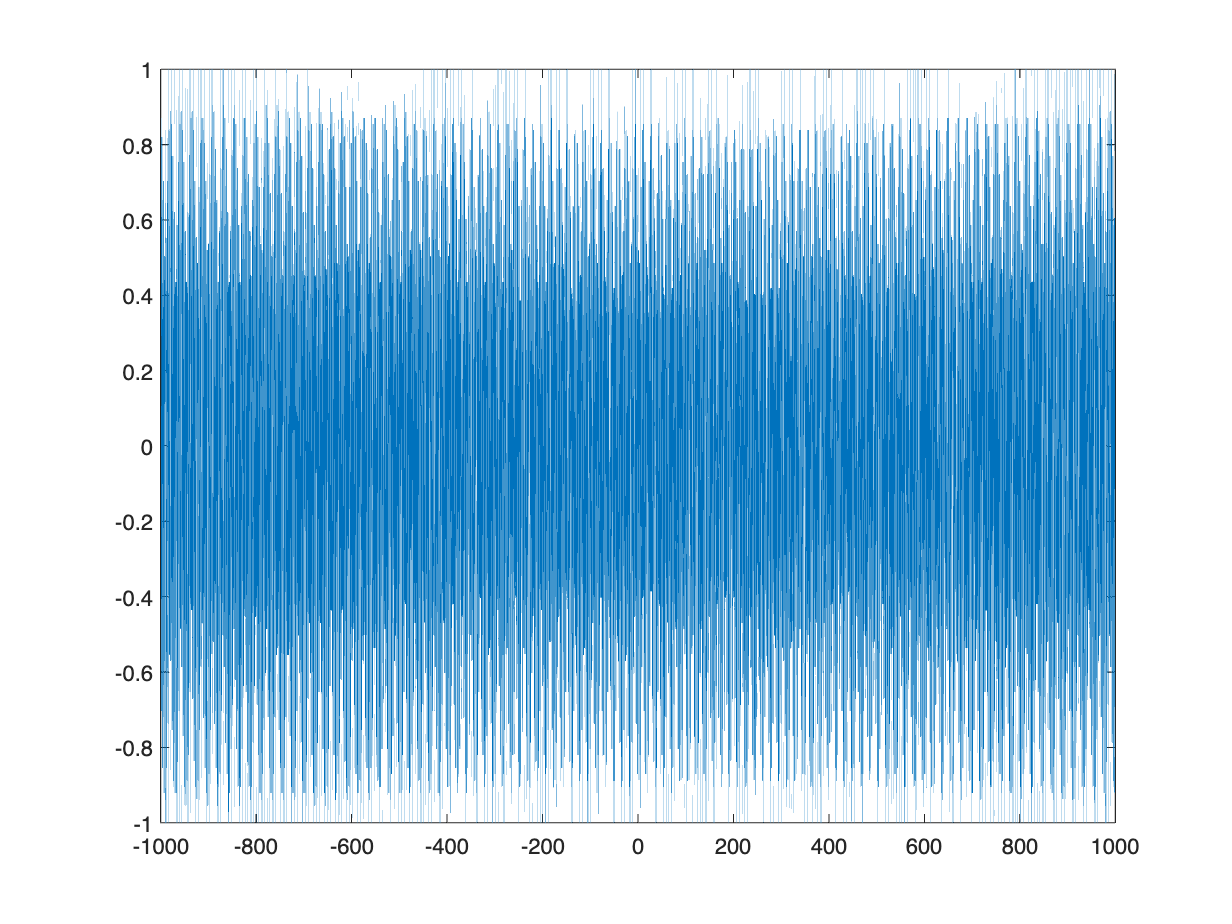

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["xaxis", "VarName2"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
scope = readtable("/Users/mh/Documents/MATLAB/scope_42.csv", opts);

data = table2array(scope); 

plot(data(:,1)/1e-9, data(:,2)); 

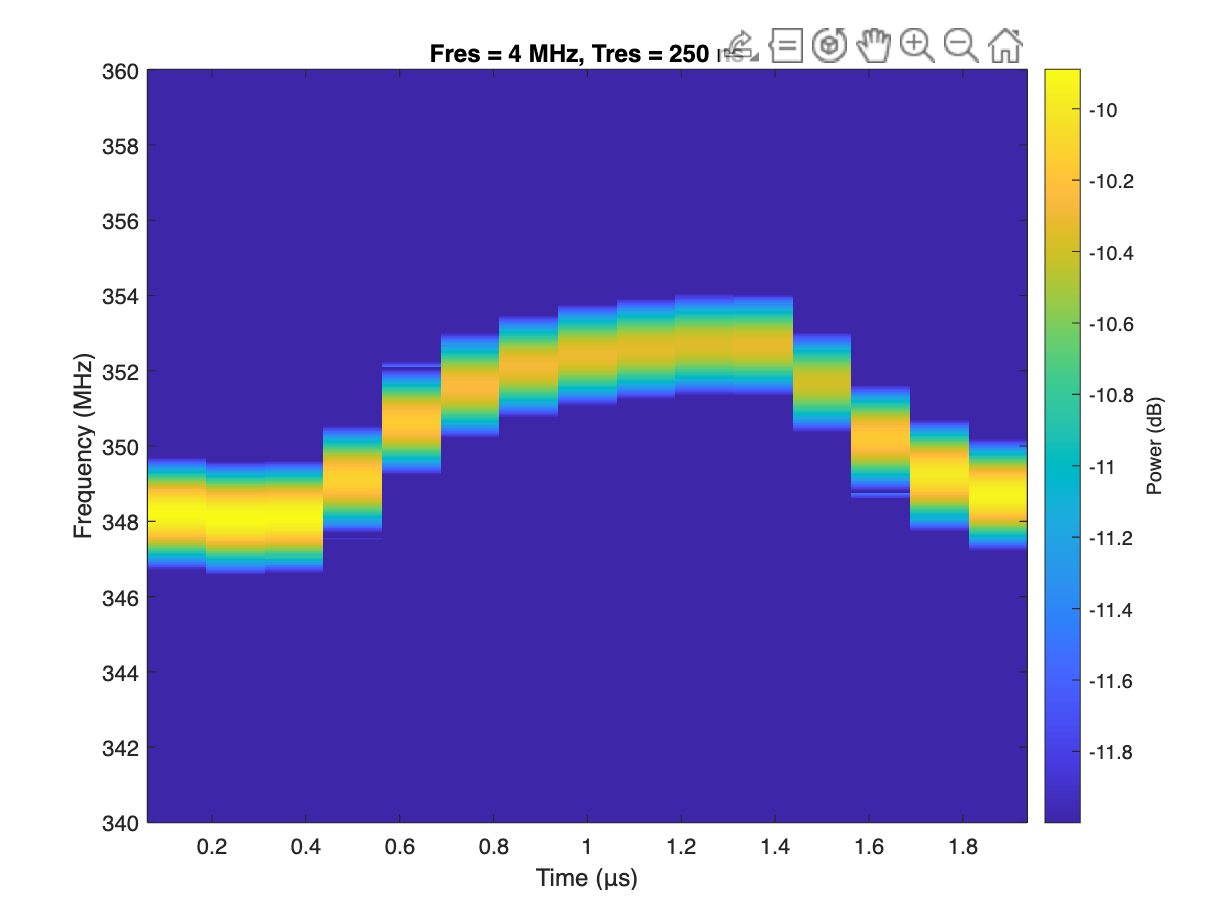



signal = data(3:end,2); time = data(3:end,1); dt = time(2)-time(1); Fs = 1/dt; 




pspectrum(signal,Fs,'spectrogram','OverlapPercent',50, ...
    'Leakage',1,'FrequencyLimits',[340, 360]*1e6, 'Reassign',true, 'MinTHreshold',-12)